## Image segmentation using region growing

DA is optimizing your problem


Best_score = 150

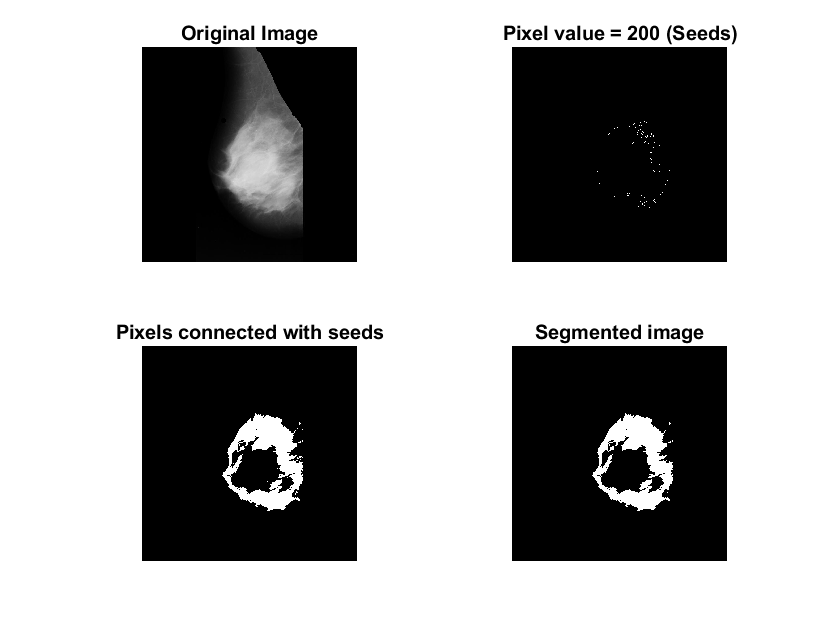

DA is optimizing your problem


Best_score = 150

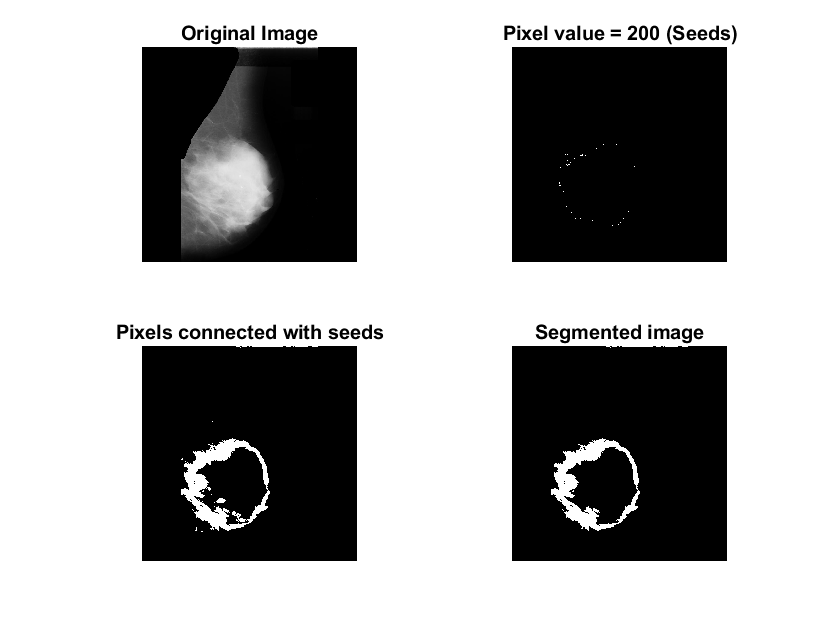

DA is optimizing your problem


Best_score = 150

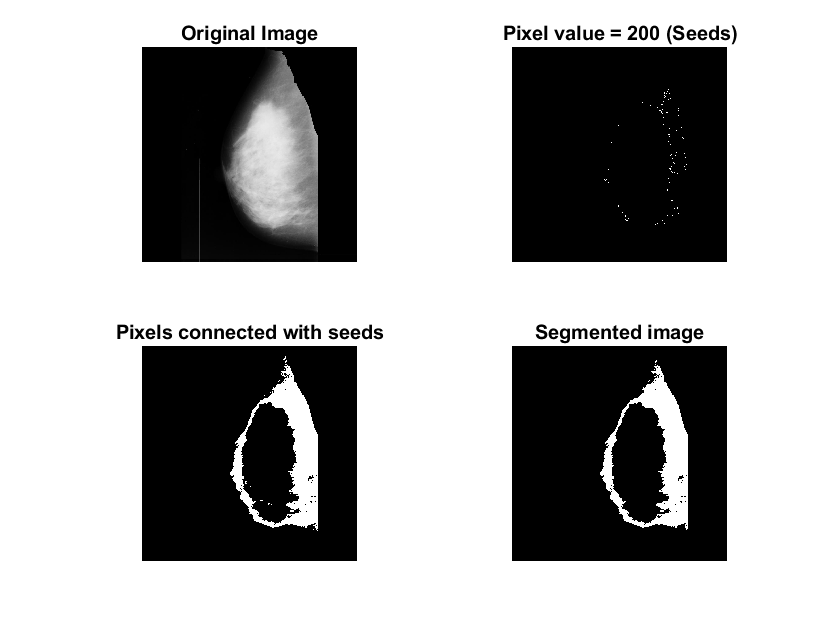

DA is optimizing your problem


Best_score = 150

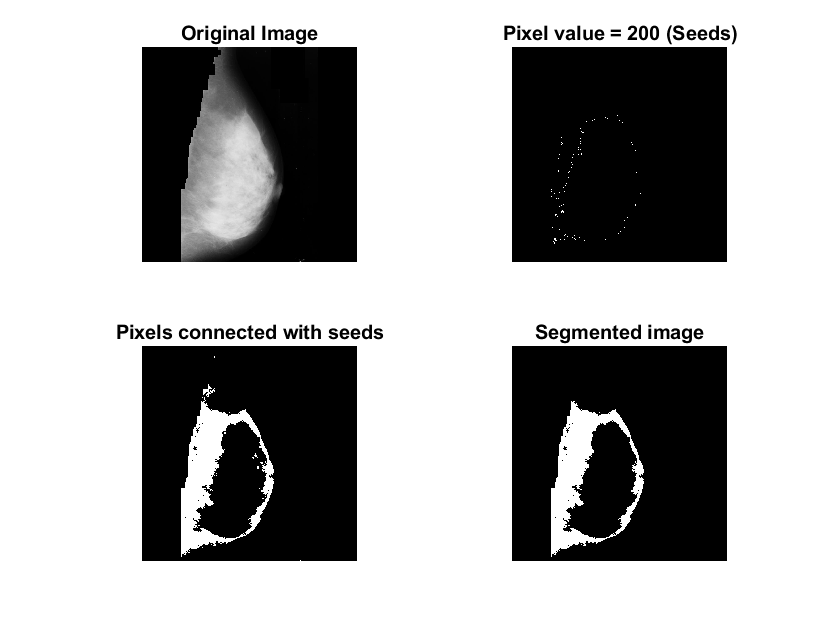

DA is optimizing your problem


Best_score = 150

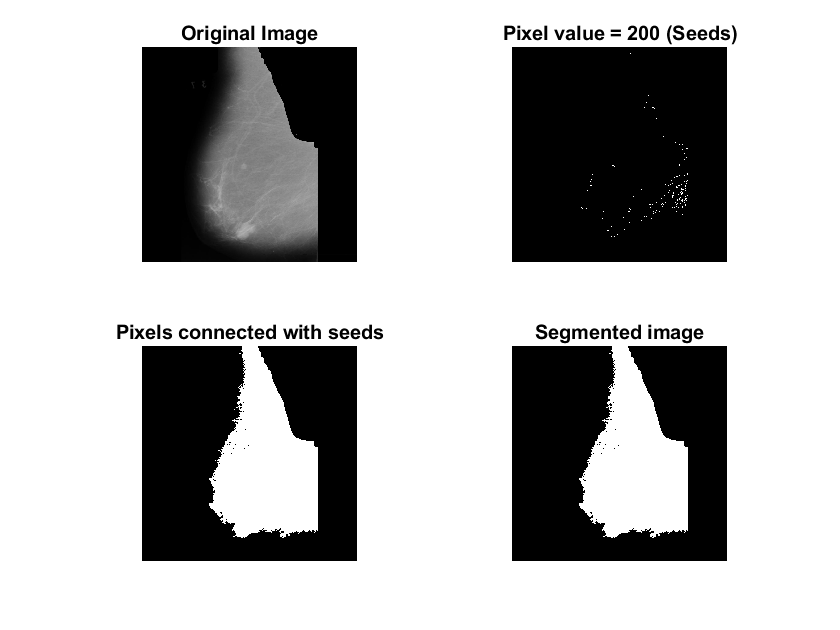

DA is optimizing your problem


Best_score = 150

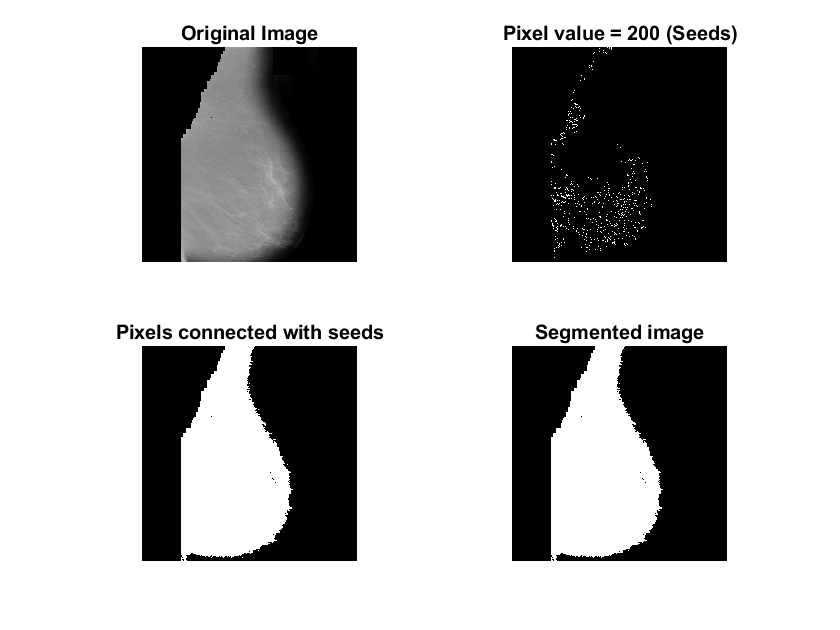

DA is optimizing your problem


Best_score = 150

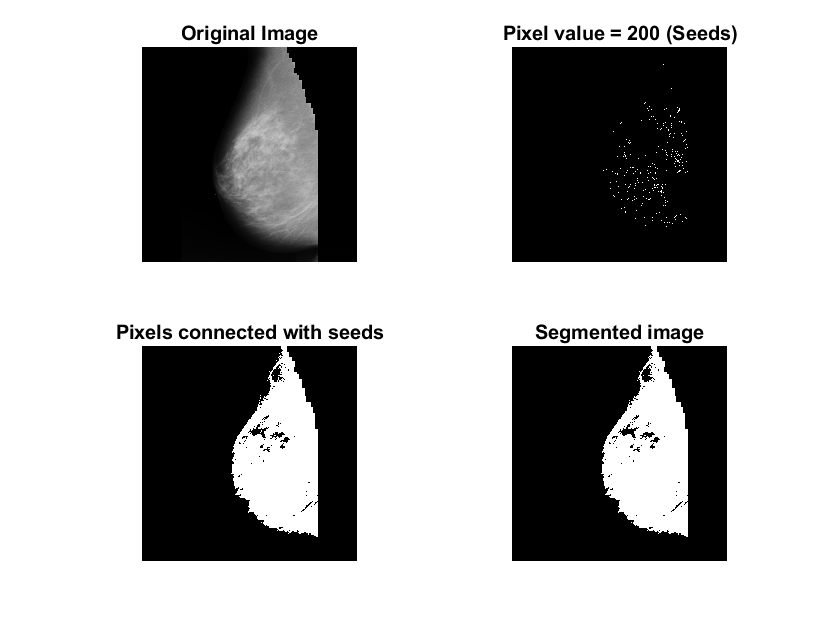

DA is optimizing your problem


Best_score = 150

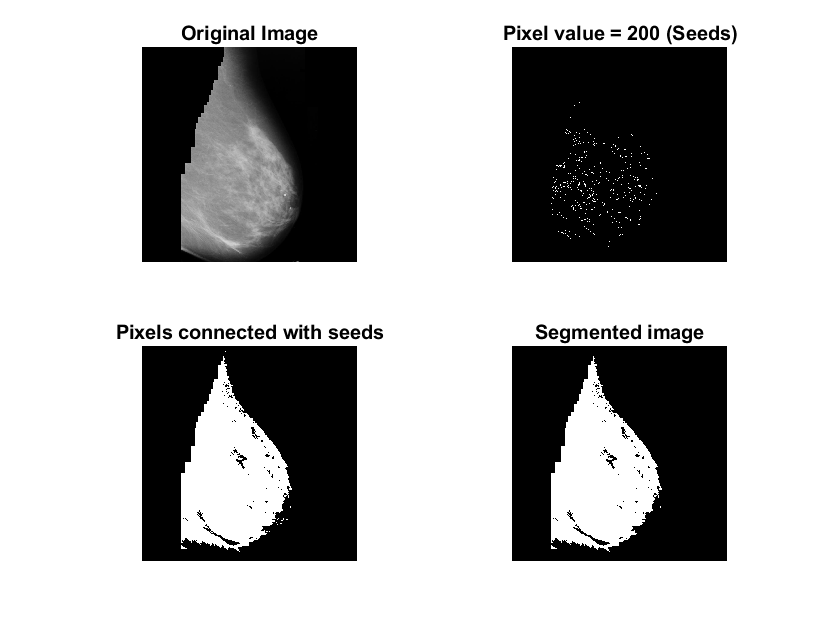

DA is optimizing your problem


Best_score = 150

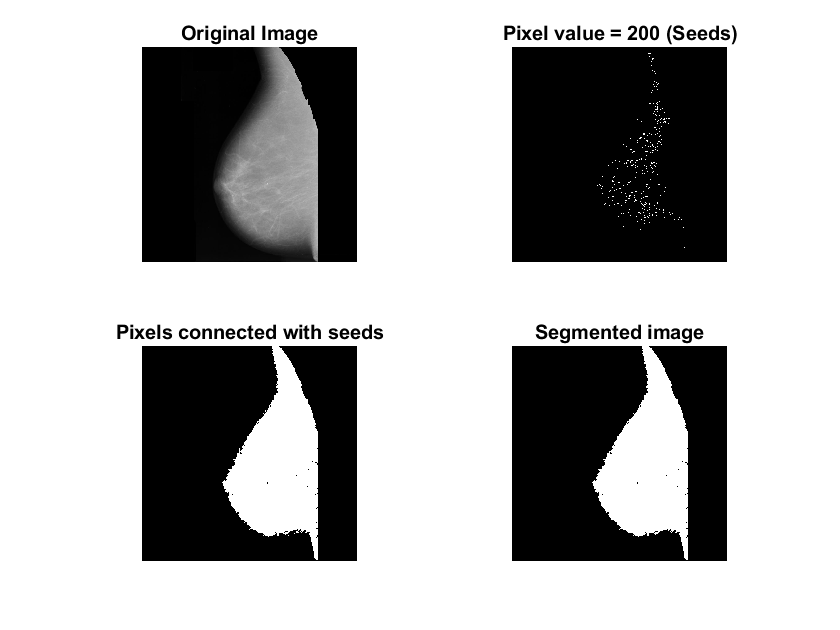

DA is optimizing your problem


Best_score = 150

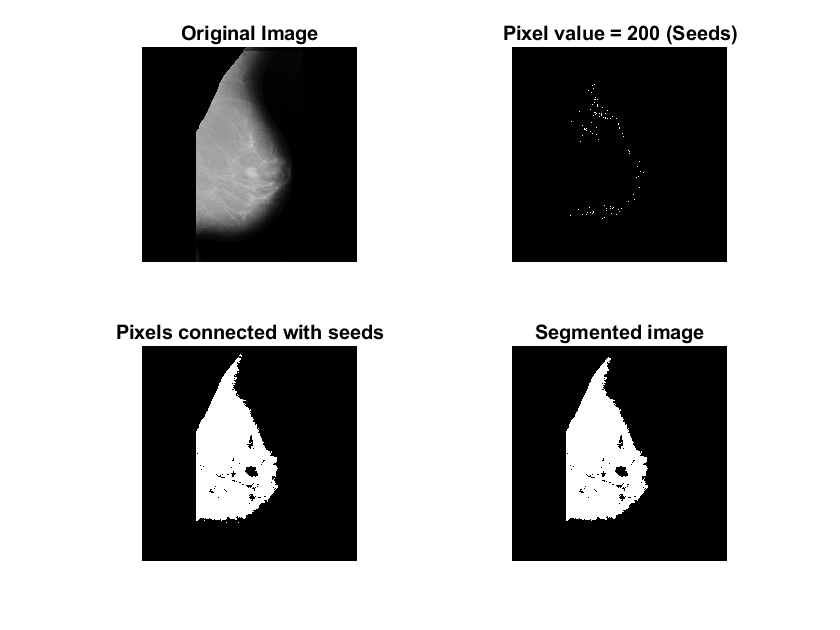

DA is optimizing your problem


Best_score = 150

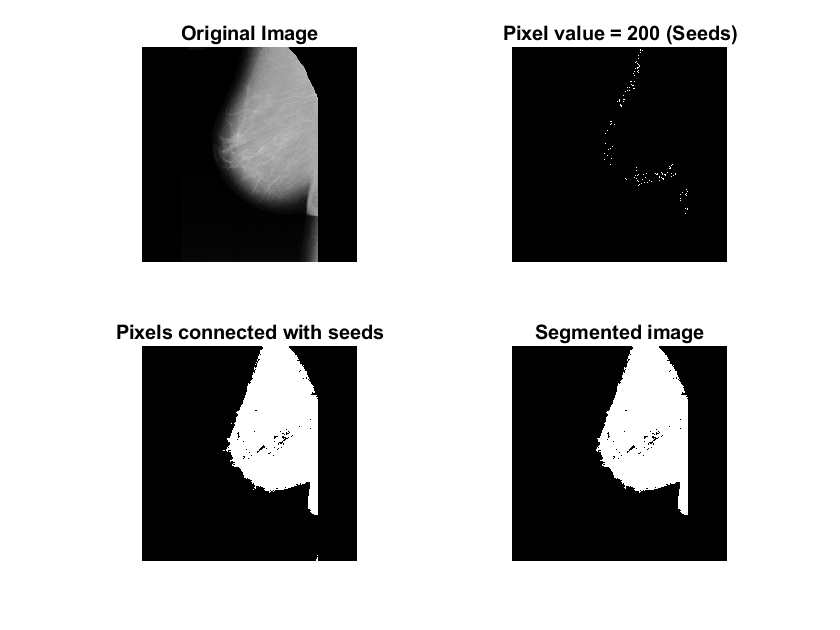

DA is optimizing your problem


Best_score = 150

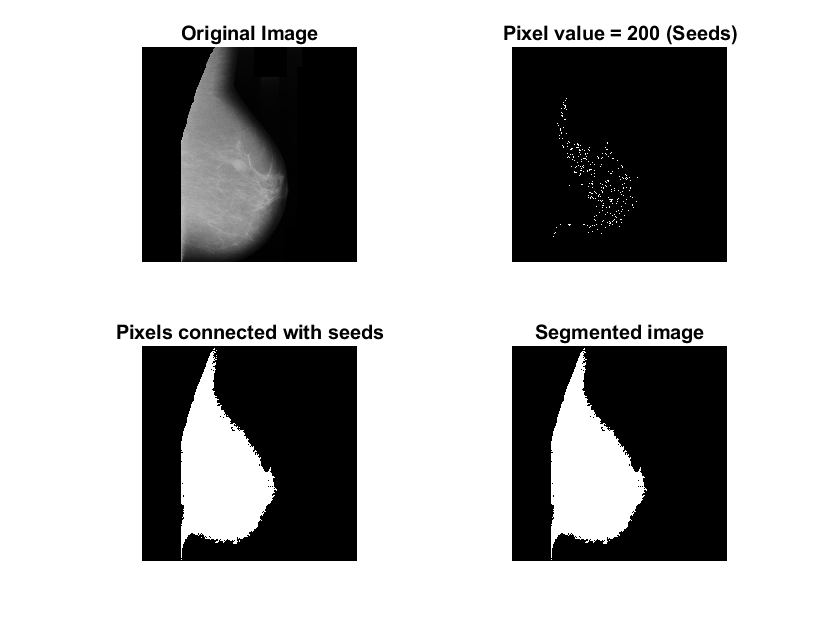

DA is optimizing your problem


Best_score = 150

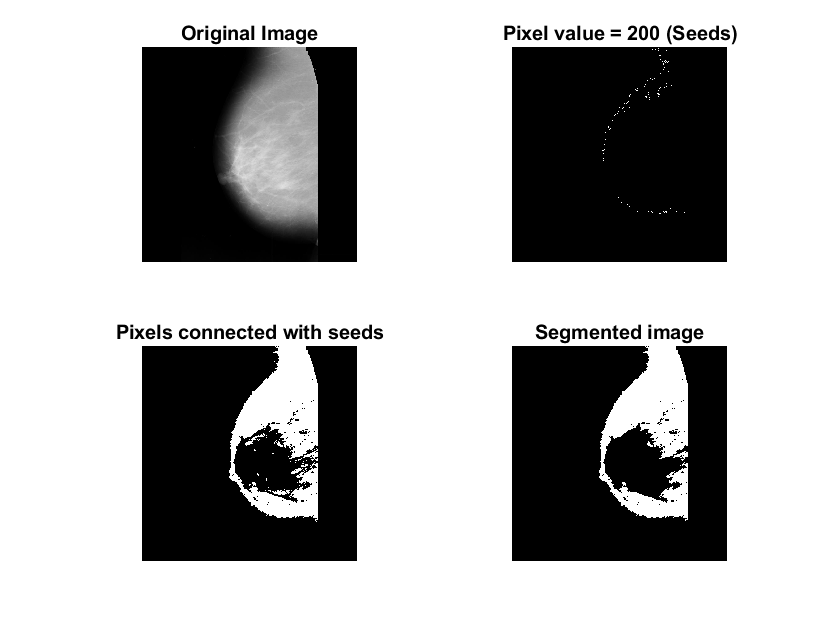

DA is optimizing your problem


Best_score = 150

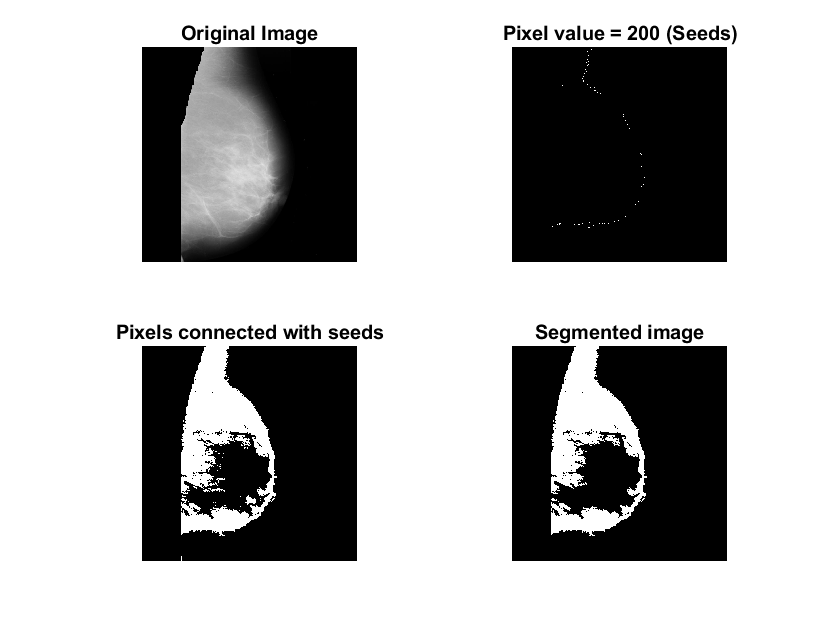

DA is optimizing your problem


Best_score = 150

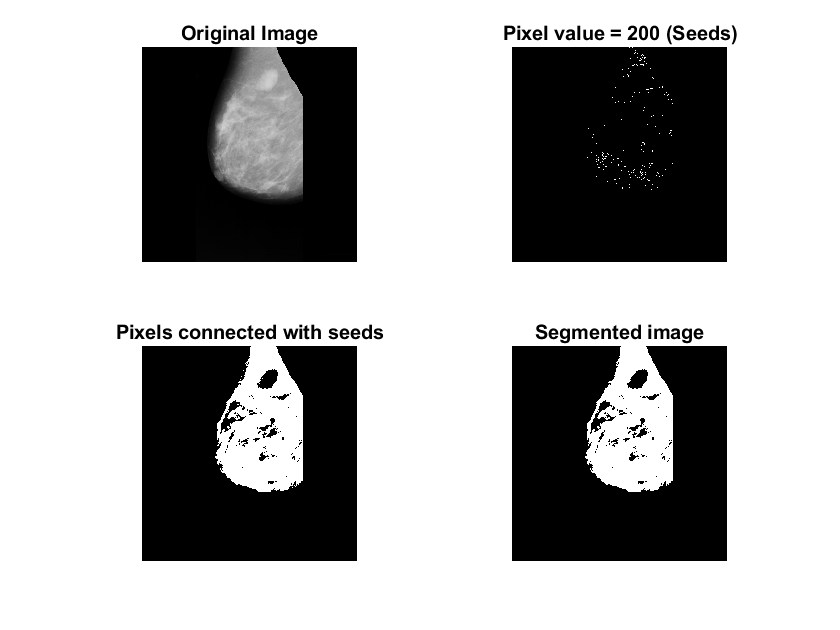

DA is optimizing your problem


Best_score = 150

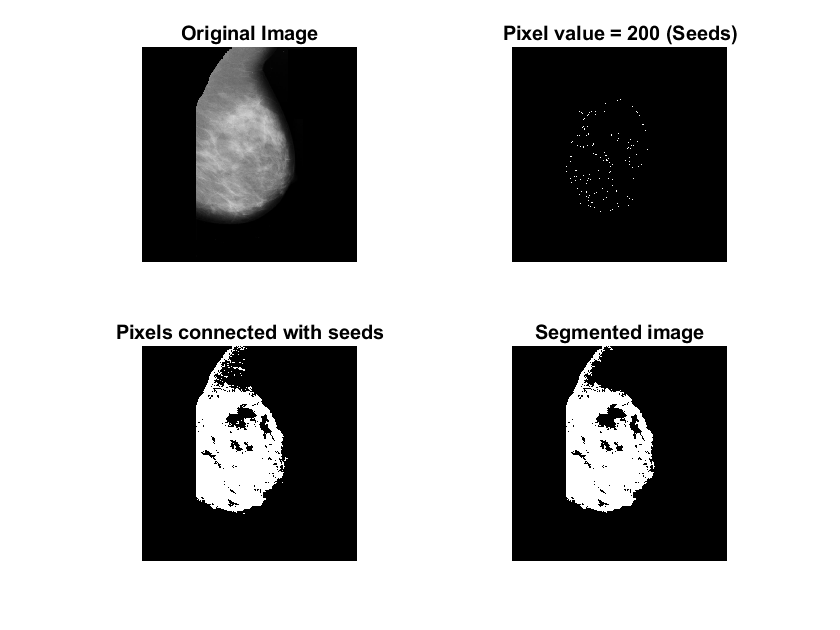

DA is optimizing your problem


Best_score = 150

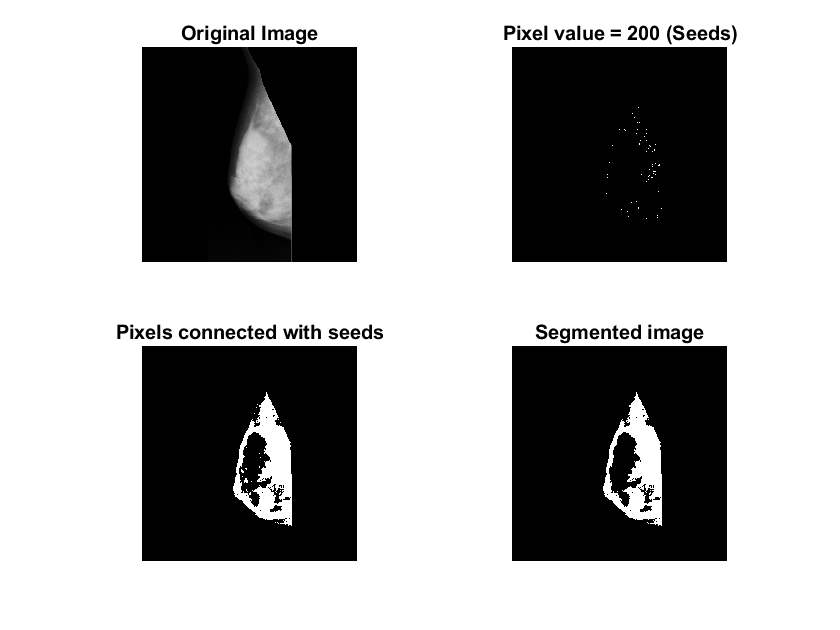

DA is optimizing your problem


Best_score = 150

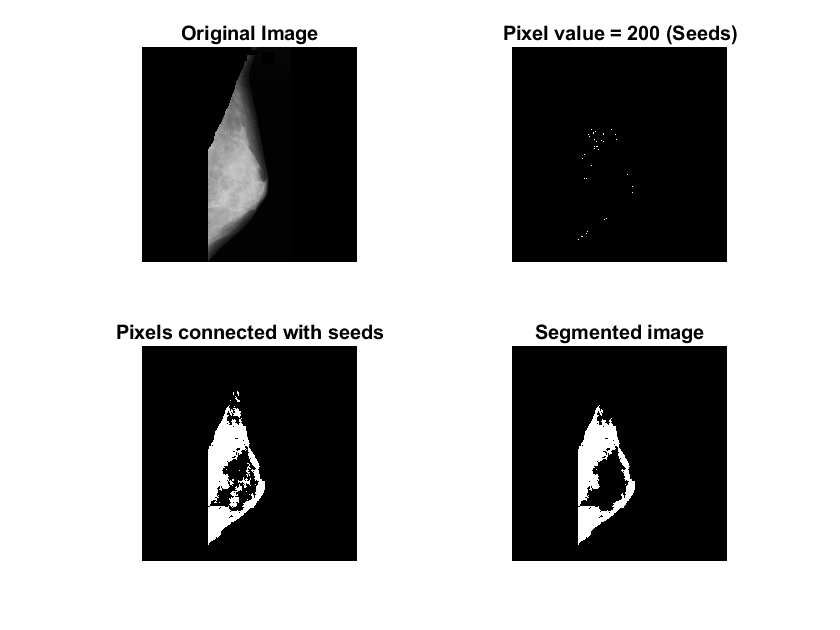

DA is optimizing your problem


Best_score = 150

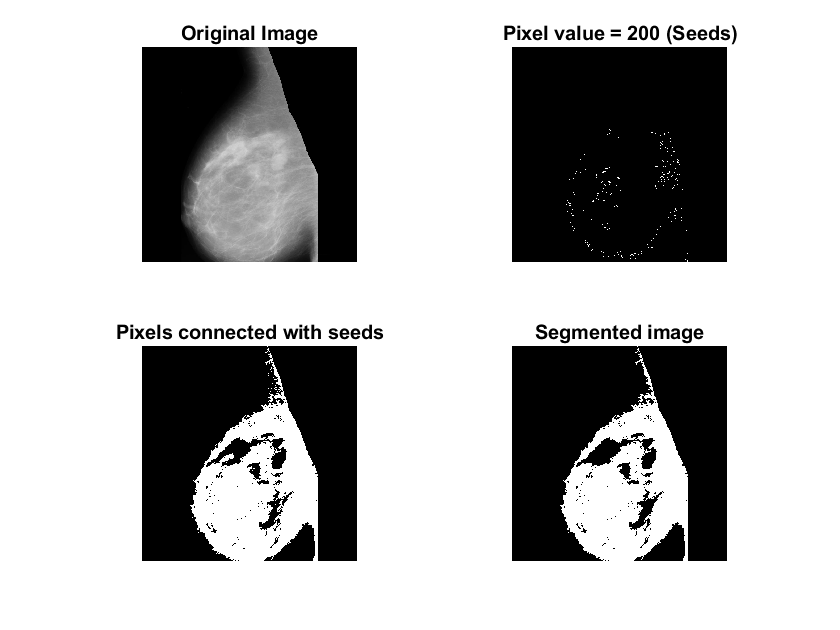

DA is optimizing your problem


Best_score = 150

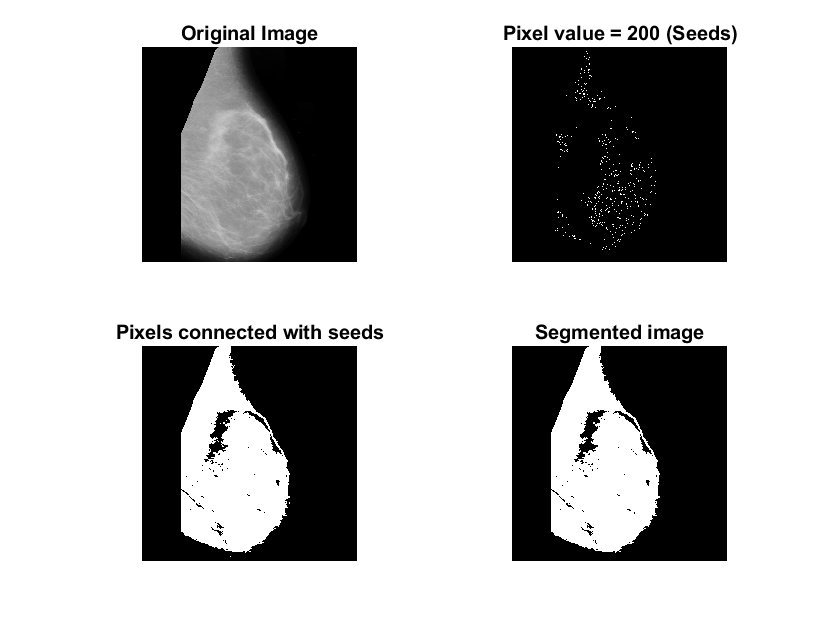

DA is optimizing your problem


Best_score = 150

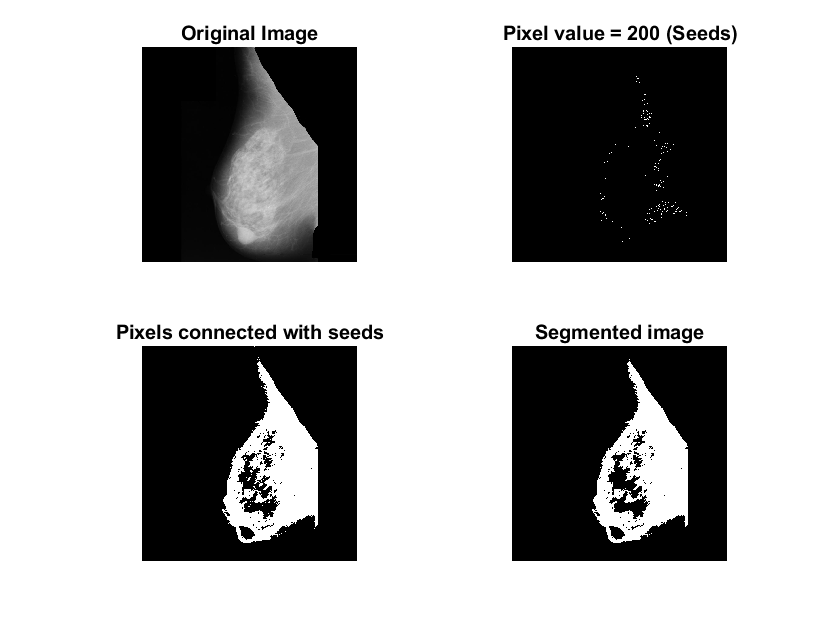

DA is optimizing your problem


Best_score = 150

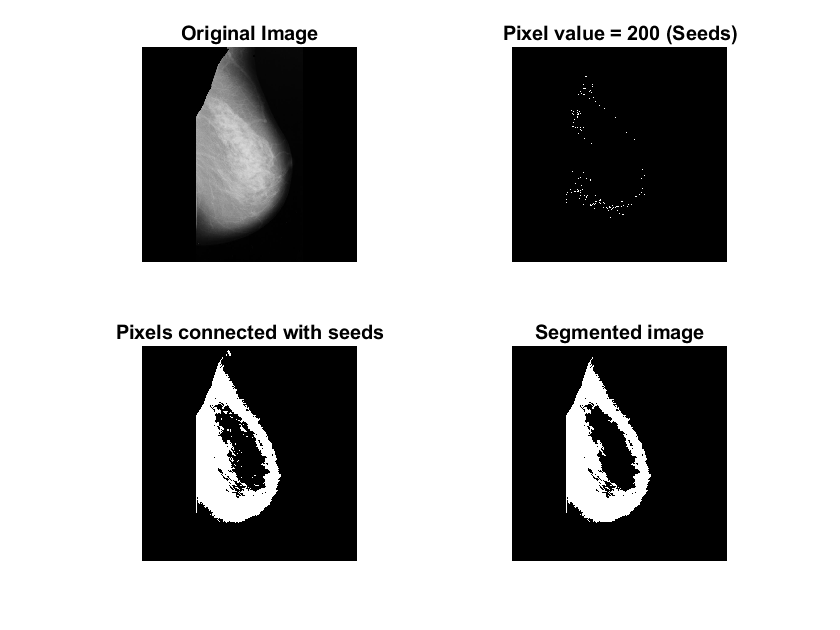

DA is optimizing your problem


Best_score = 150

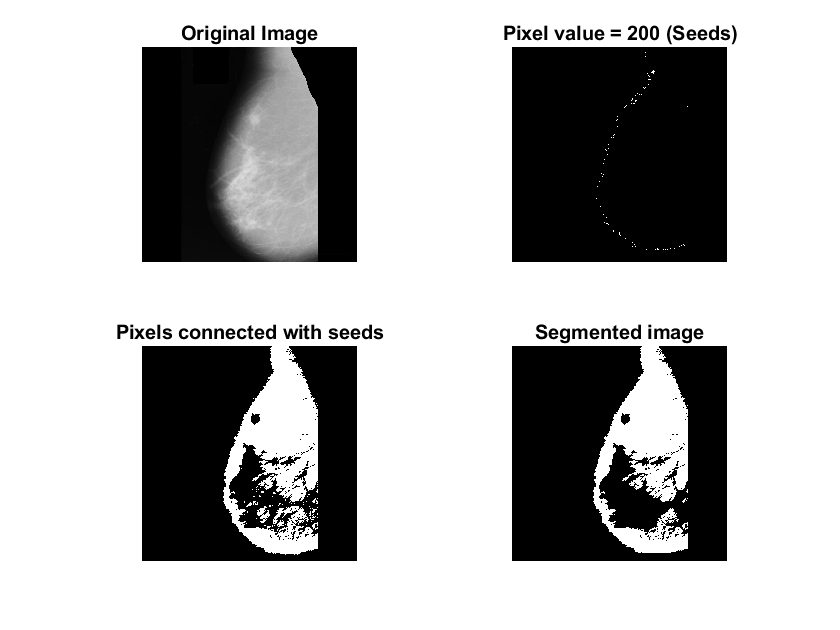

DA is optimizing your problem


Best_score = 150

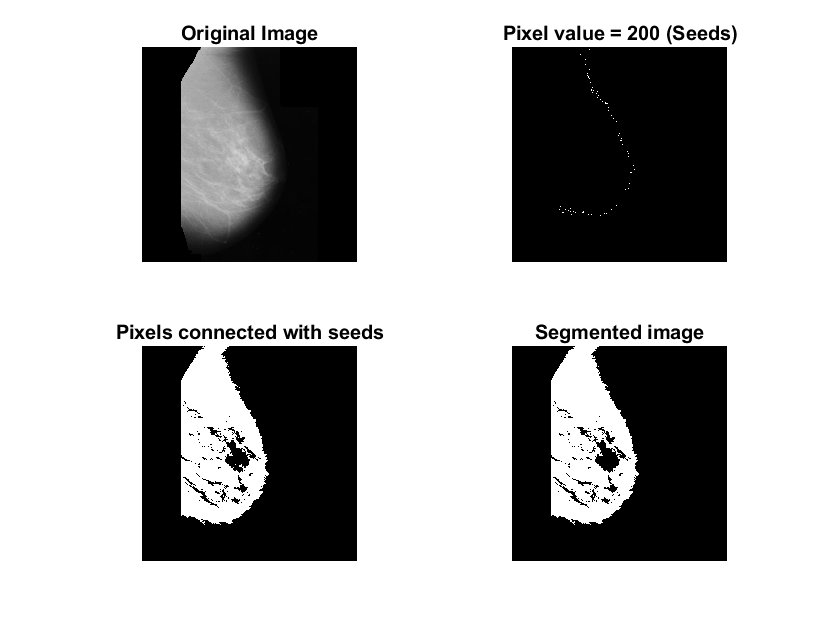

DA is optimizing your problem


Best_score = 150

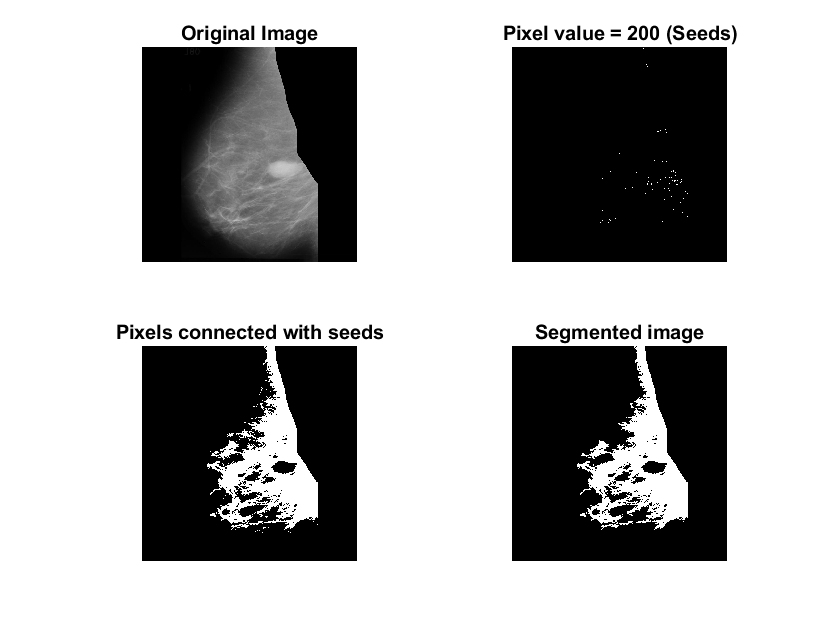

DA is optimizing your problem


Best_score = 150

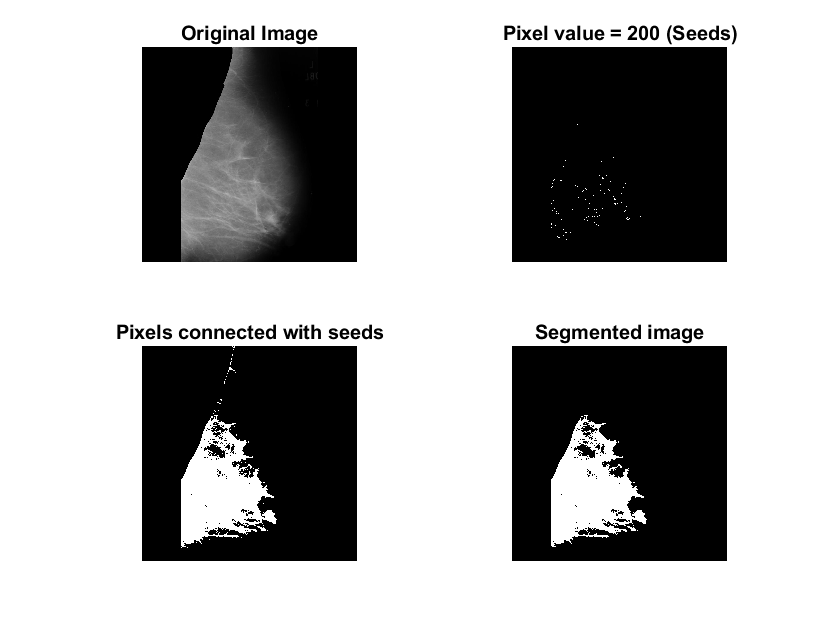

DA is optimizing your problem


Best_score = 150

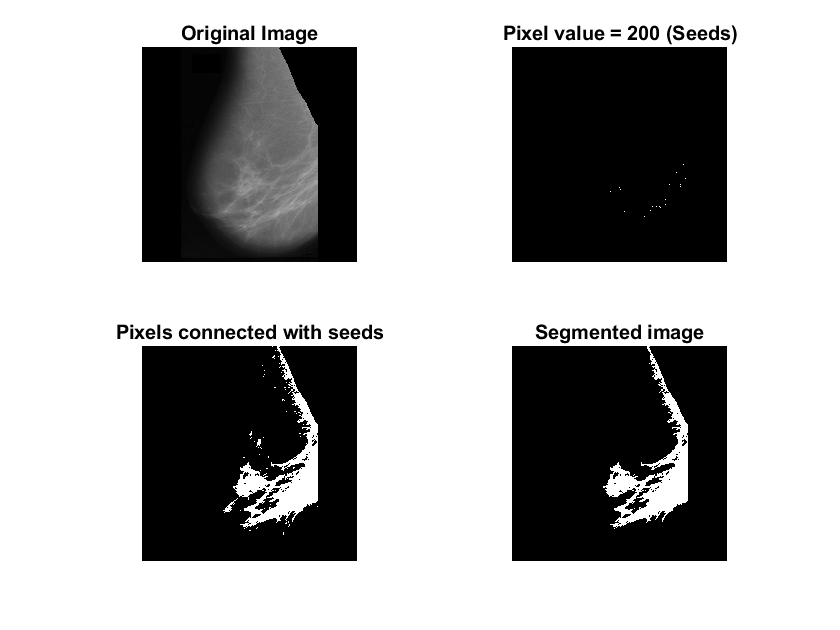

DA is optimizing your problem


Best_score = 150

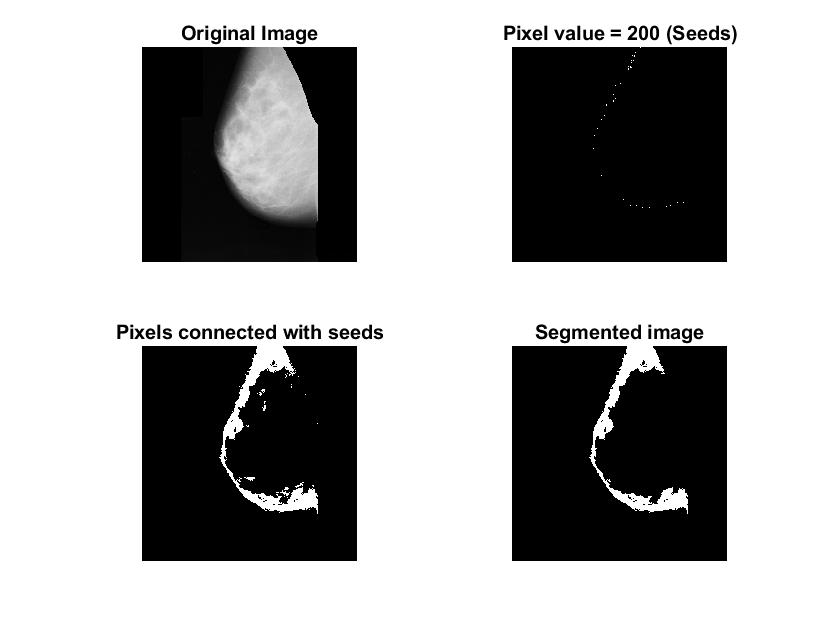

DA is optimizing your problem


Best_score = 150

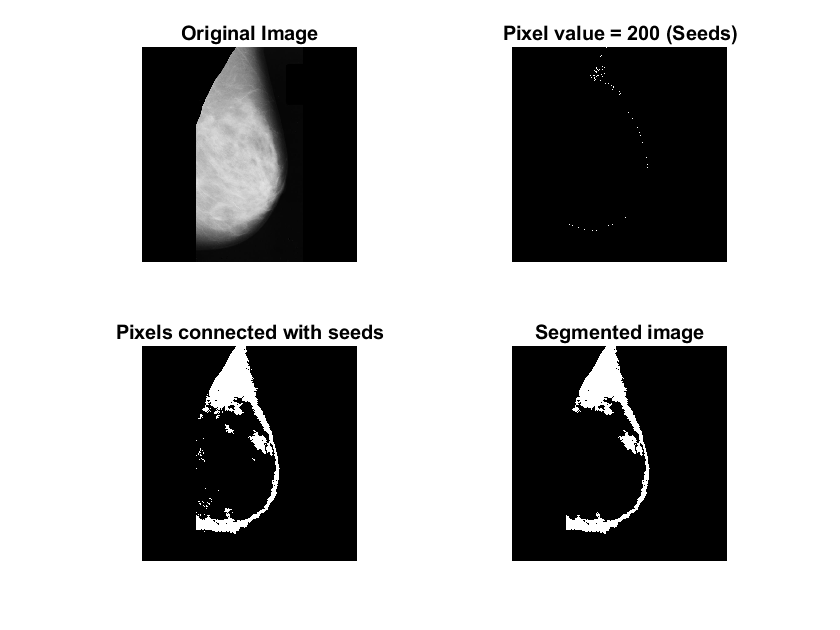

DA is optimizing your problem


Best_score = 150

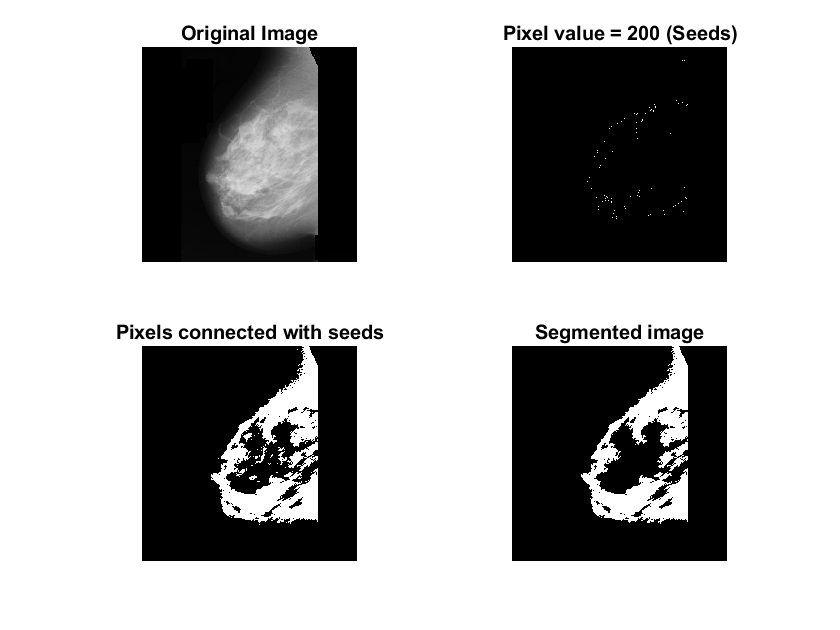

DA is optimizing your problem


Best_score = 150

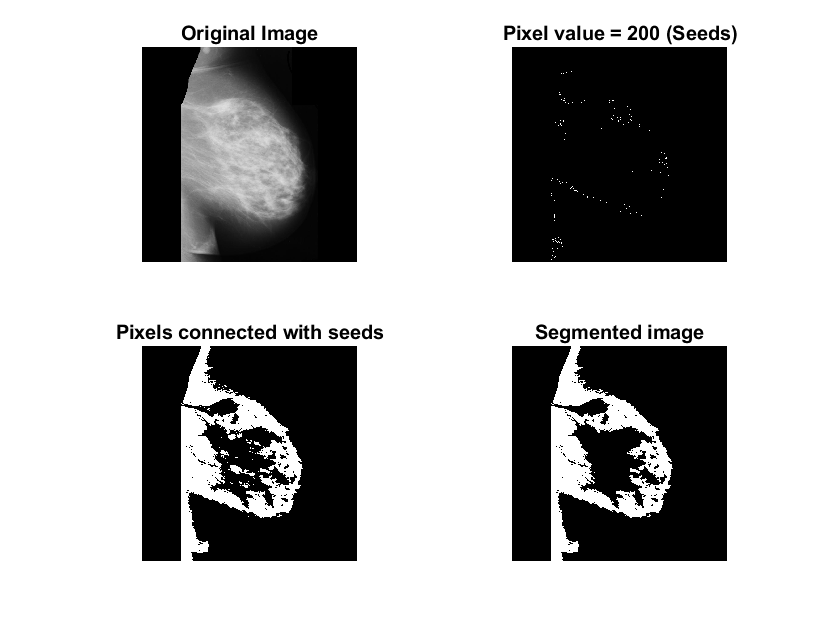

DA is optimizing your problem


Best_score = 150

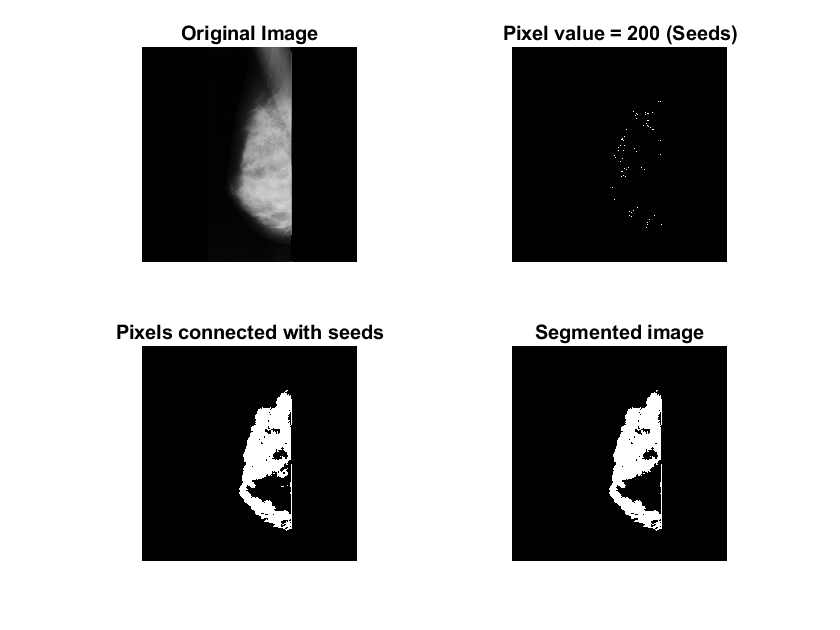

DA is optimizing your problem


Best_score = 150

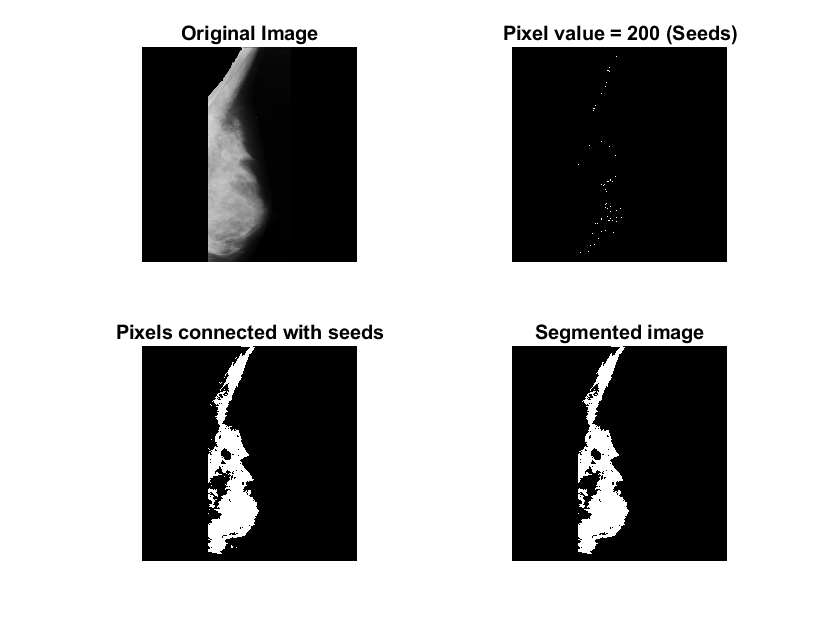

DA is optimizing your problem


Best_score = 150

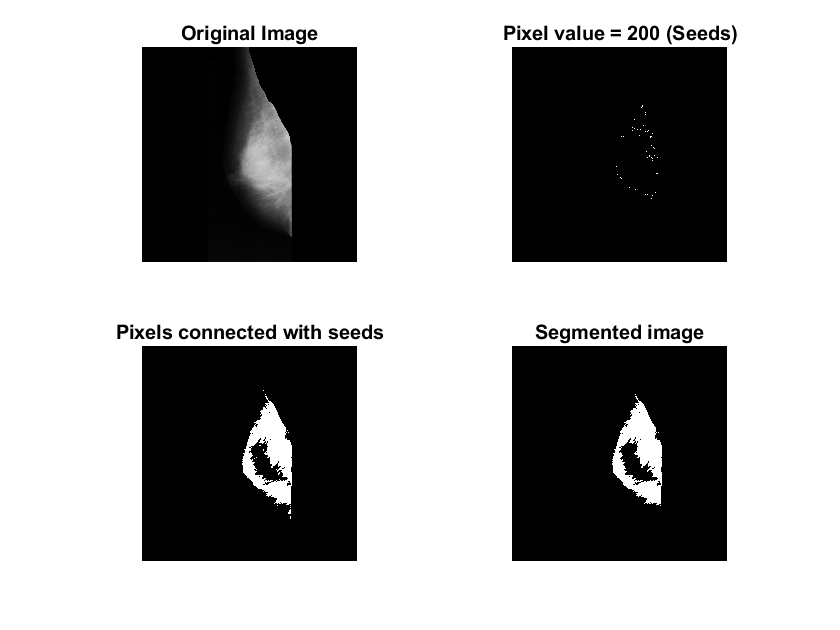

DA is optimizing your problem


Best_score = 150

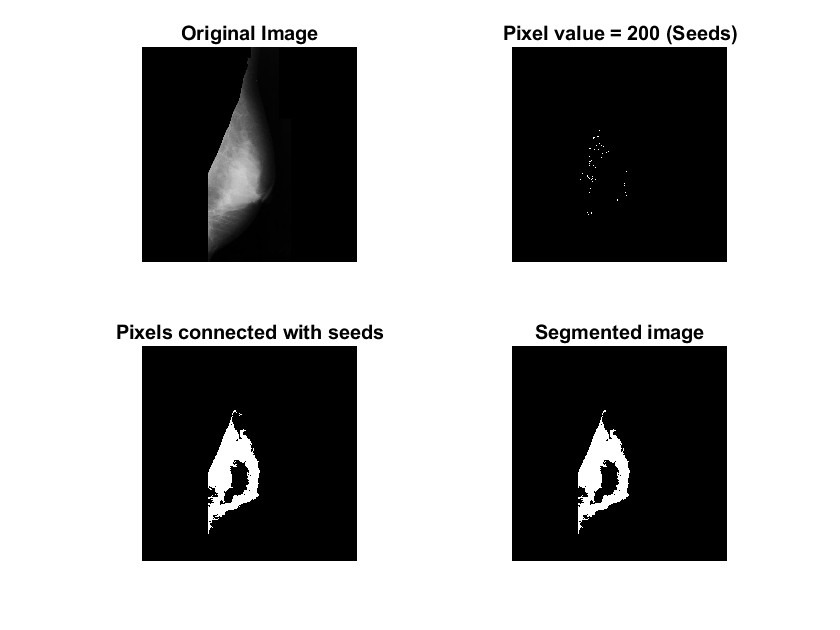

DA is optimizing your problem


Best_score = 150

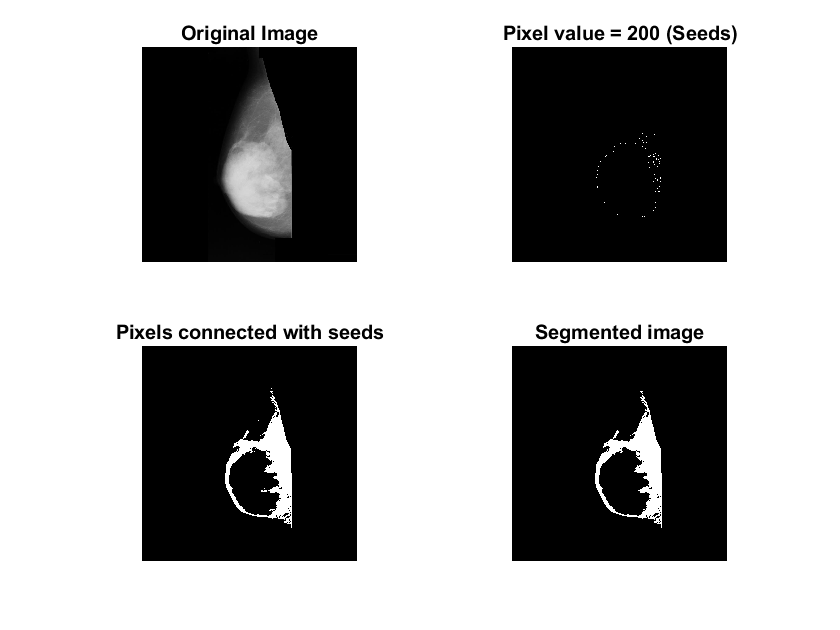

DA is optimizing your problem


Best_score = 150

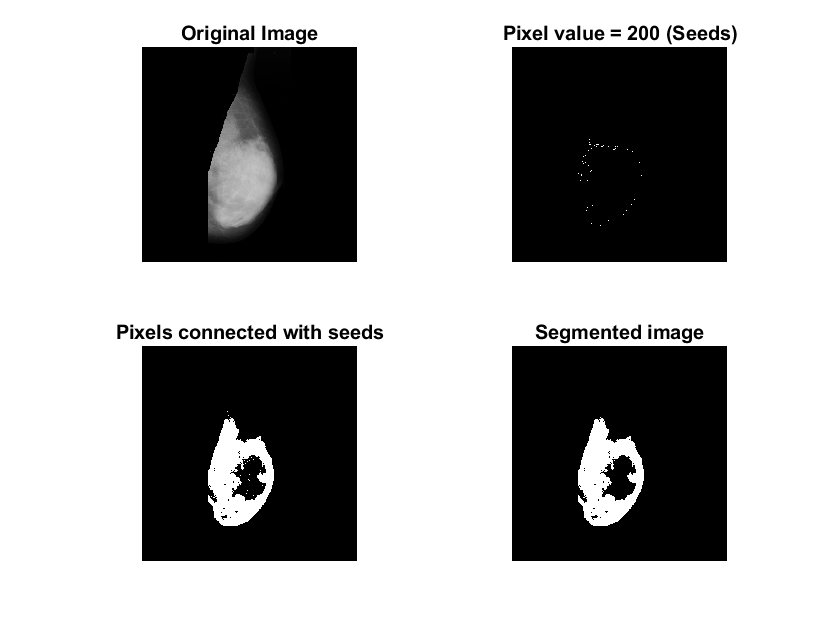

DA is optimizing your problem


Best_score = 150

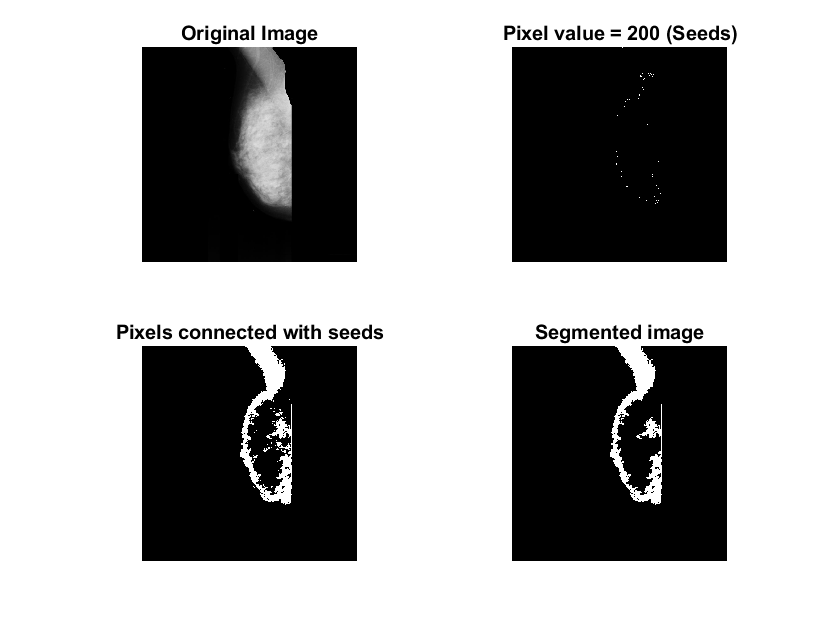

DA is optimizing your problem


Best_score = 150

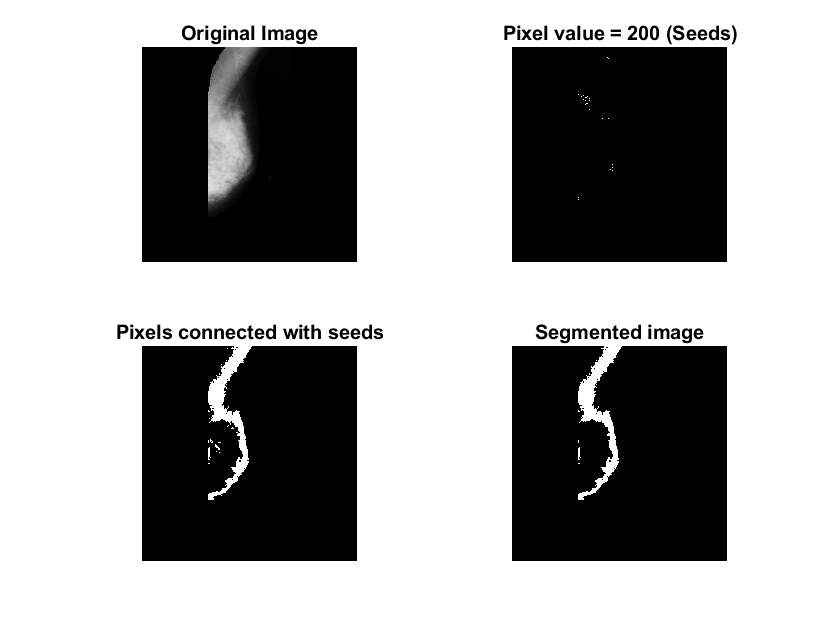

DA is optimizing your problem


Best_score = 150

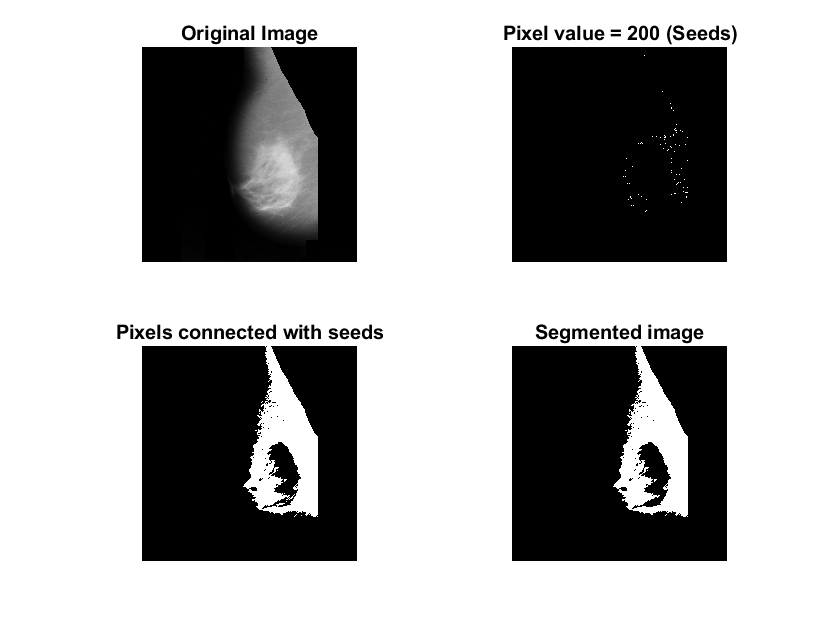

DA is optimizing your problem


Best_score = 150

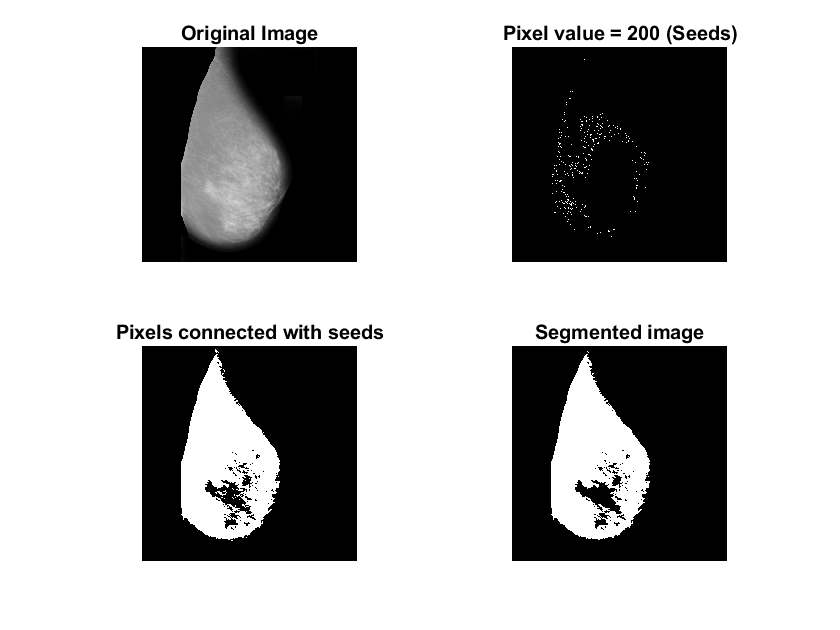

DA is optimizing your problem


Best_score = 150

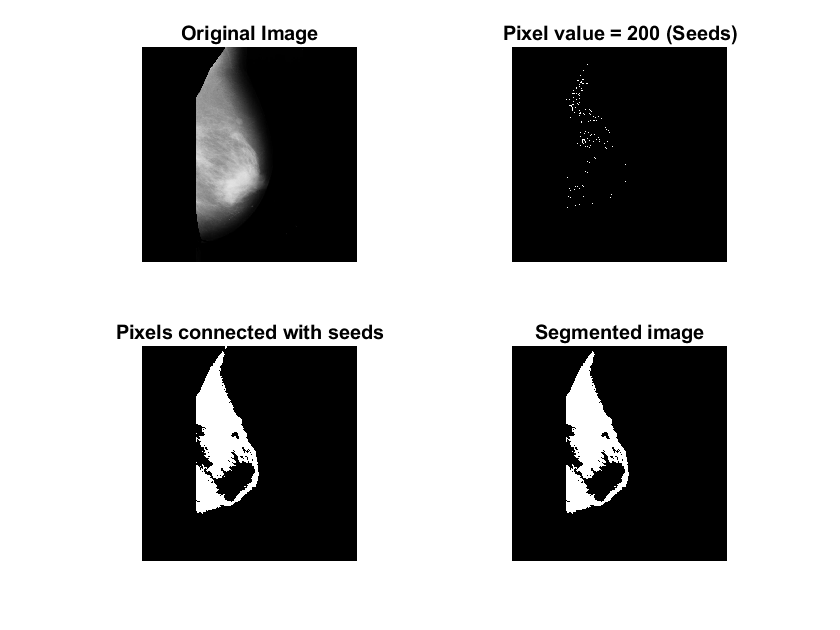

DA is optimizing your problem


Best_score = 150

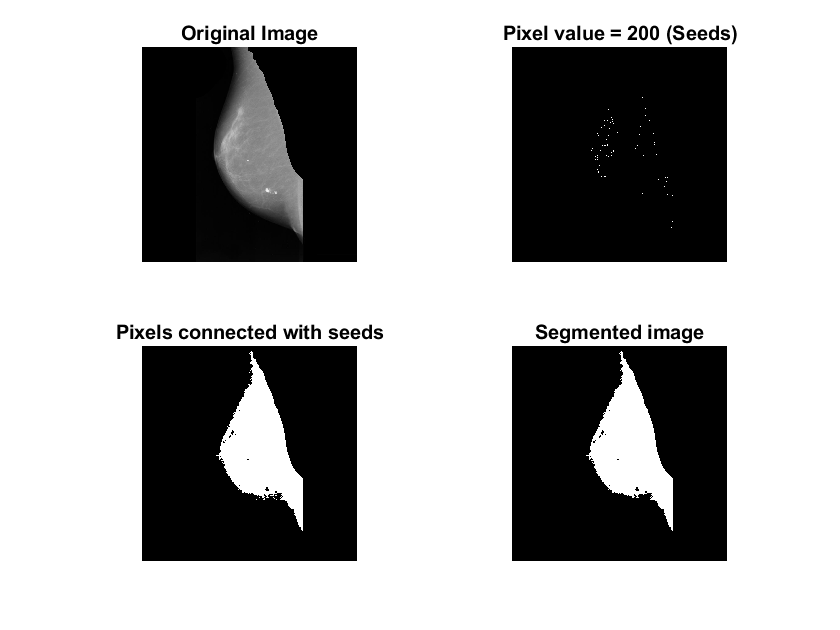

DA is optimizing your problem


Best_score = 150

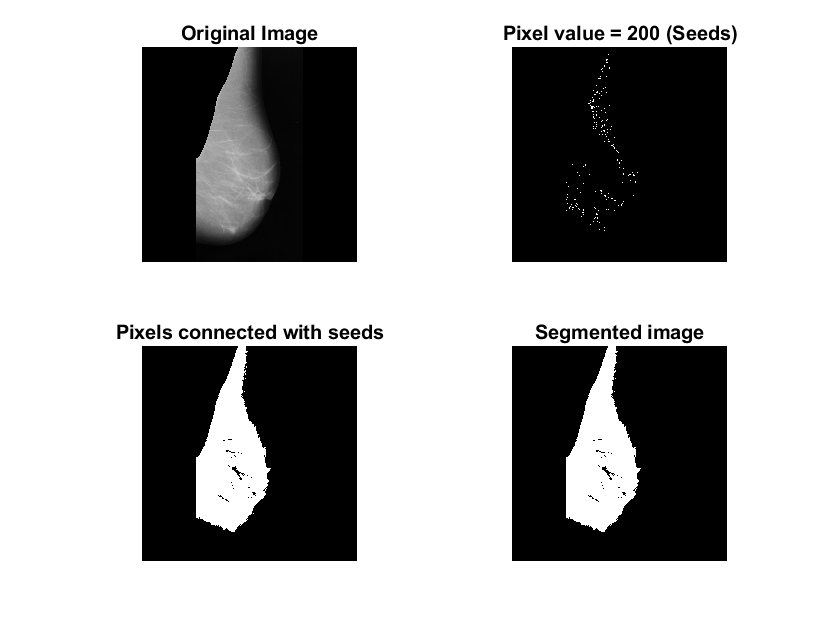

DA is optimizing your problem


Best_score = 150

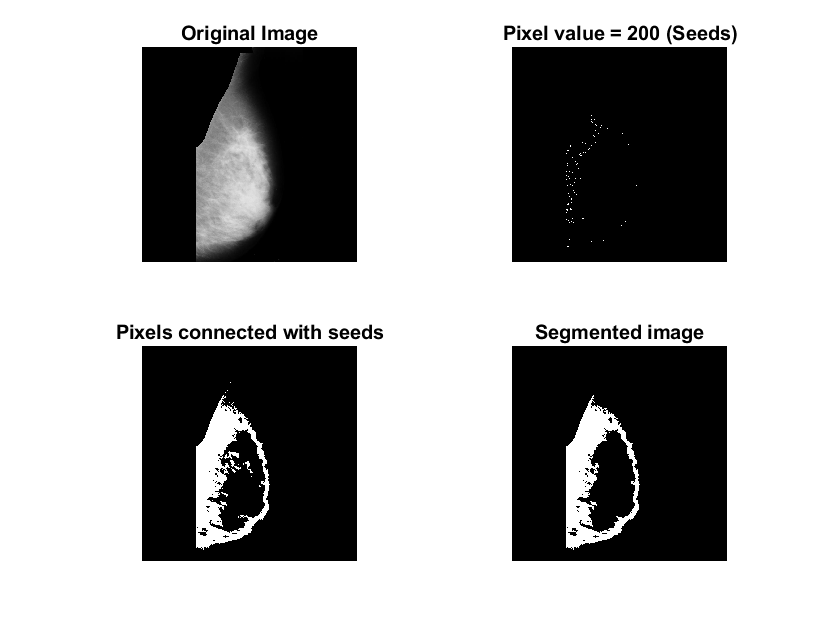

DA is optimizing your problem


Best_score = 150

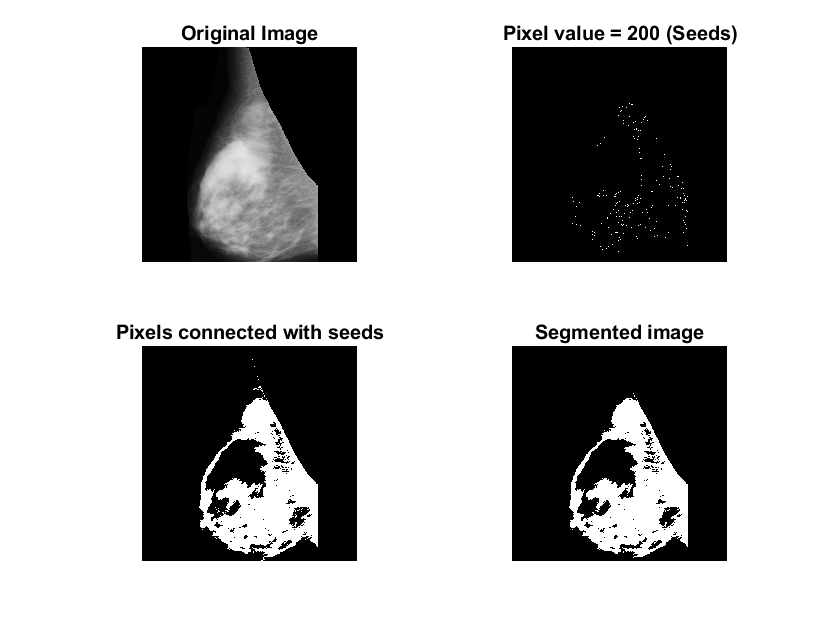

DA is optimizing your problem


Best_score = 150

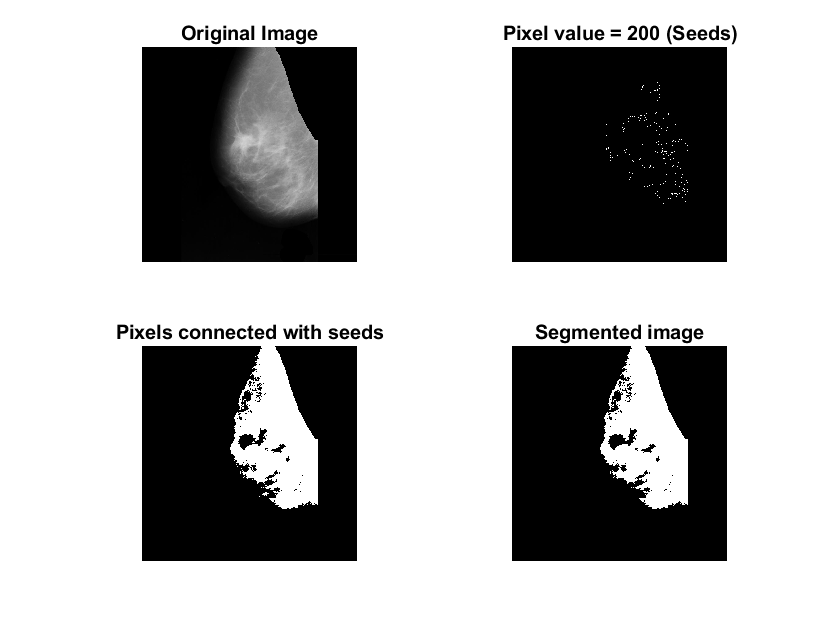

DA is optimizing your problem


Best_score = 150

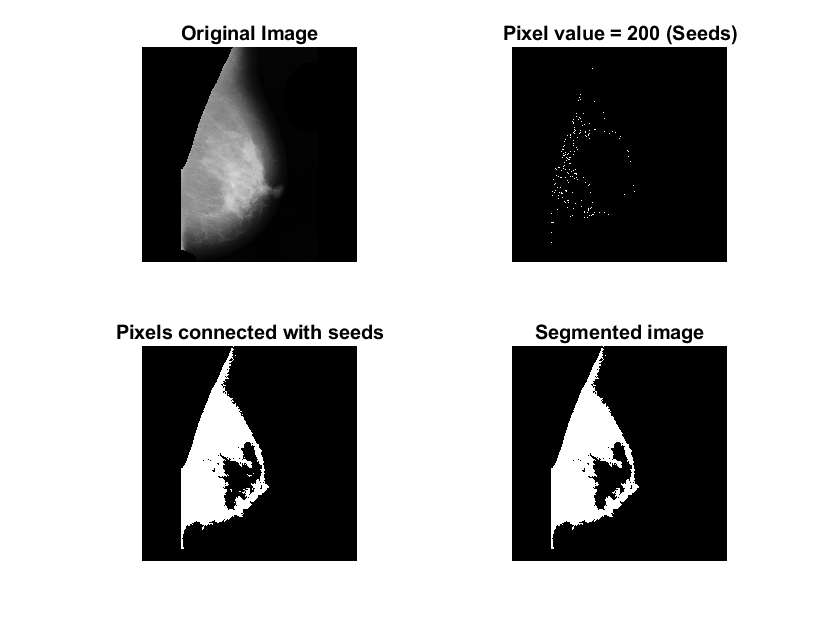

DA is optimizing your problem


Best_score = 150

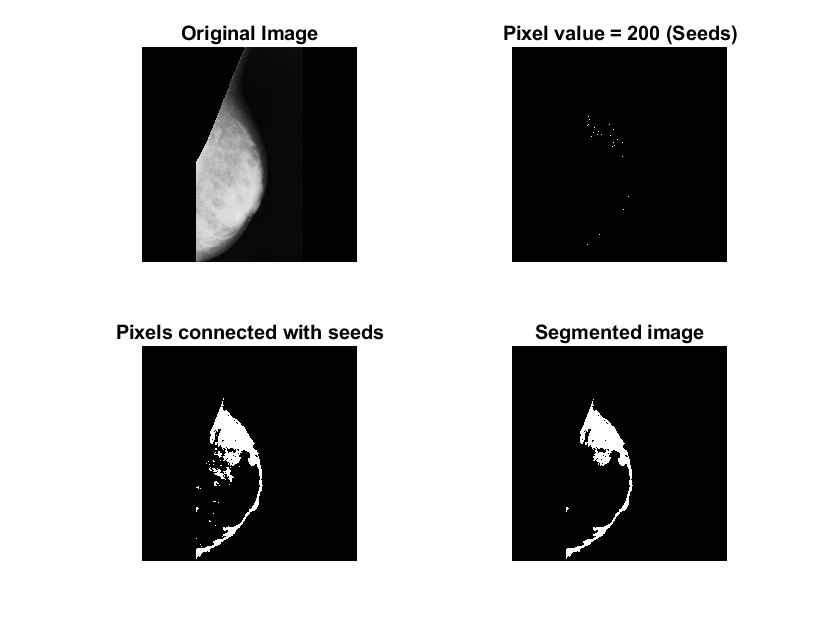

DA is optimizing your problem


Best_score = 150

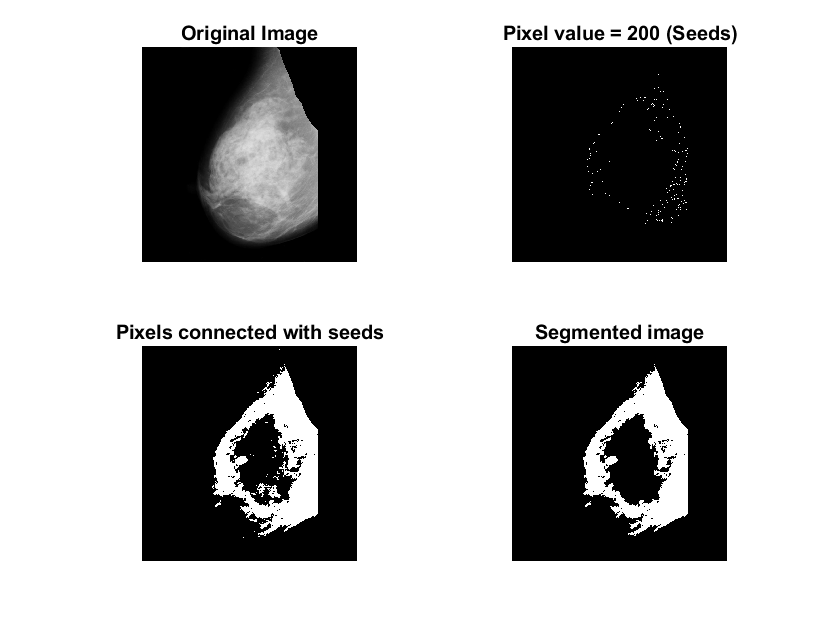

%breastImds="mdb001.jpg";
breastImds=imageDatastore("MIAS(no muscle)");
%put images file location here
%breastImds = imageDatastore(...
%    "C:\Users\Daniel Kee\Documents\Monash\FYP\FIT3162\fit3162\Code\MIAS(no muscle)");
%img="MIAS(no muscle)/mdb020.jpg";
while(hasdata(breastImds))
    SearchAgents_no=50;
    Max_iteration=100;
    lb=150; %%
    ub=300; %%
    dim=1;
    fobj=@costFunction;
    [Best_score,Best_pos,cg_curve]=DA(SearchAgents_no,Max_iteration,lb,ub,dim,fobj);
    Best_score
    
    I = read(breastImds);
    %region_growing(breastImds,180); %old result %define seed
    region_growing(I,Best_score); %da result
end

function region_growing(breastImds,seed)
%I = imread(breastImds);
I = breastImds;
I = rgb2gray(I);

I = double(I);
figure, subplot(2,2,1),imshow(uint8(I)),title('Original Image');
Seeds = [seed];
SI = I == Seeds;
subplot(2,2,2), imshow(SI, []),title('Pixel value = 200 (Seeds)');
T = 30;
TI = false(size(I));

for i = 1:length(Seeds)
    seed_val = Seeds(i);
    S = abs(I-seed_val) <= T;
    TI = TI | S;
end

subplot(2,2,3), imshow(TI, []),title('Pixels connected with seeds');
IM = imreconstruct(SI,TI);
subplot(2,2,4), imshow(IM, []),title('Segmented image');
end

function Cost = costFunction(x)
    Cost = x+1;
end